# piDMD w/ dimensional reduction via LSUN for Conservative systems

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, [http://doi.org/10.1098/rspa.2022.0576](http://doi.org/10.1098/rspa.2022.0576)

- Brunton, S. L., & Kutz, J. N. (2022). *Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control* (2nd ed.). Cambridge: Cambridge University Press.

- jitKutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear 
close all
setup

databook_matlab-master exists.
databook_DATA exists.
DATA exists.
Copying VORTALL.mat ...
piDMD-main exists.
Add path piDMD-main/src


## Parameter Setup

nModes4PODtrunc = 15; 
nCoefs4LSUNtrunc = 2;  
nrows = 199;
ncols = 449;

## Source Data Preparation

load("../../../data/databook_DATA/DATA/VORTALL");
ut = reshape(VORTALL,nrows,ncols,[]);

## Source Data Visualization

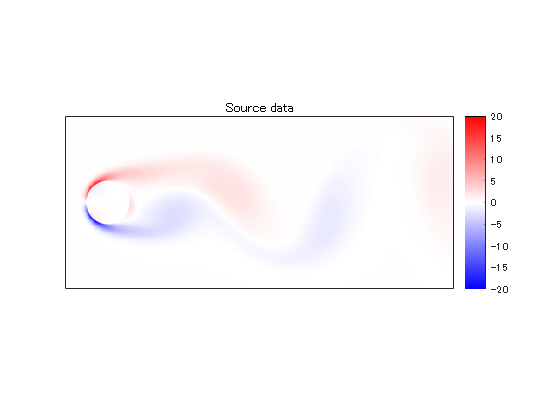

clims = 1.1*[min(ut,[],'all') max(ut,[],'all')];
nFrames = size(ut,3);
him = [];
for iFrame = 1:nFrames
    x = ut(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
        title('Source data')
    end
    drawnow
end

% exportgraphics

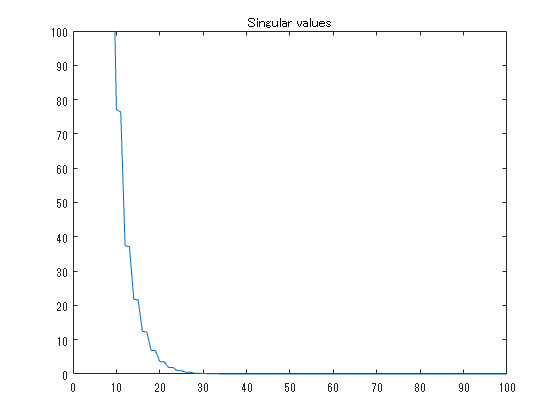

% POD truncation
Xorg = reshape(ut,[],size(ut,3));
Xo = Xorg(:,1:end-1);
%
[~,So,~] = svds(Xo,100);
plot(diag(So))
axis([0 100 0 100])
title('Singular values')

drawnow

%Yo = Xorg(:,2:end);
[Psiorg,Sorg,Vorg] = svds(Xo,nModes4PODtrunc);
Atorg = Sorg*Vorg';

% Approximation
Xtilde = Psiorg*Atorg;
mean((Xo-Xtilde).^2,'all')

ans = 3.2466e-05

## Noisy Data Preparation

Noise energy set to 20% of signal energy

varu = var(ut,0,'all');
varw = 0.2*varu; 
sigmaw = sqrt(varw);
vt = ut + sigmaw * randn(size(ut),'like',ut);

## Noisy Data Visualization

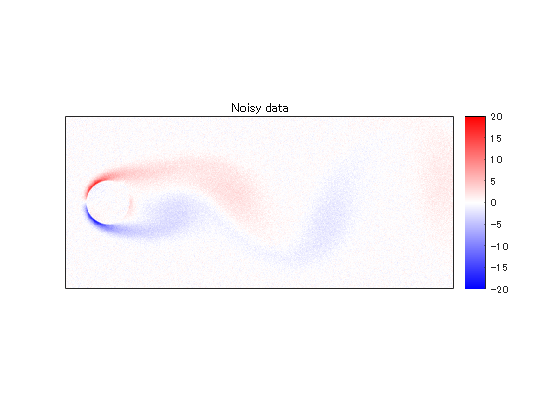

him = [];
for iFrame = 1:nFrames
    x = vt(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
        title('Noisy data')
    end
    drawnow
end

% exportgraphics
save("../../../results/noisyflow_"+replace(num2str(sigmaw),'.','_'),"ut","vt")

## Experiments

### Define data matrix

Xnoisy = reshape(vt,[],size(vt,3));
Xn = Xnoisy(:,1:end-1);
Yn = Xnoisy(:,2:end);

## exact DMD w/ leading POD mode truncation

[exA, exVals, exVecs] = piDMD(Xn,Yn,'exact',nModes4PODtrunc); % Original exact DMD

## Time evolution via exact DMD 

Rn = zeros(size(Xn)+[0 1],'like',Xn);
b = exVecs'*Xn(:,1);
precoefs = b;
for iFrame = 1:nFrames-1
    coefs = diag(exVals)*precoefs;
    Rn(:,iFrame+1) = real(exVecs*coefs); % Take real only for numerical error correction
    precoefs = coefs;
end

### Project back to original space

rte = reshape(Rn,nrows,ncols,[]);

## Reconstruction Data Visualization

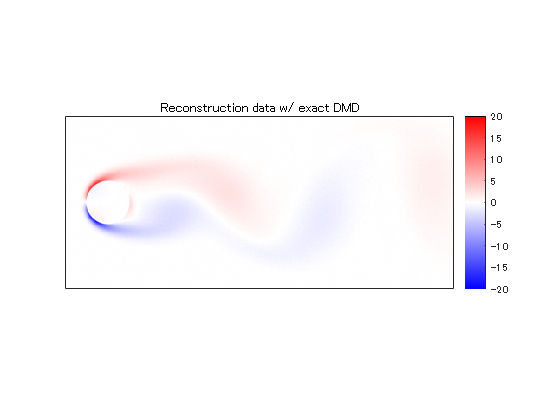

him = [];
for iFrame = 1:nFrames-1
    x = rte(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
        title('Reconstruction data w/ exact DMD')
    end
    drawnow
end

## piDMD w/ leading POD mode truncation

- Apply POD

- Project data onto the leading POD modes

- Apply piDMD

### piDMD w/ inside POD mode truncation

[piA0, piVals0, piVecs0, projA0] = piDMD(Xn,Yn,'orthogonal',nModes4PODtrunc); % Original piDMD

### piDMD w/ outside POD mode truncation  (for validation)

% Project X and Y onto principal components
[Psi,~,~] = svds(Xn,nModes4PODtrunc);
Xproj= Psi'*Xn; Yproj = Psi'*Yn; 
[piA1, piVals1] = piDMD(Xproj,Yproj,'orthogonal'); 
piApod = @(x) Psi*piA1(Psi'*x);

% Assesment 
assert(mean((piVals0-piVals1).*conj(piVals0-piVals1))<1e-9)
assert(mean((piApod(Xn)-piA0(Xn)).^2,'all')<1e-9)

## Time evolution via piDMD 

Rn = zeros(size(Xn)+[0 1],'like',Xn);
b = piVecs0'*Xn(:,1);
precoefs = b;
for iFrame = 1:nFrames-1
    coefs = diag(piVals0)*precoefs;
    Rn(:,iFrame+1) = real(piVecs0*coefs); % Take real only for numerical error correction
    precoefs = coefs;
end

### Project back to original space

rtn = reshape(Rn,nrows,ncols,[]);

## Reconstruction Data Visualization

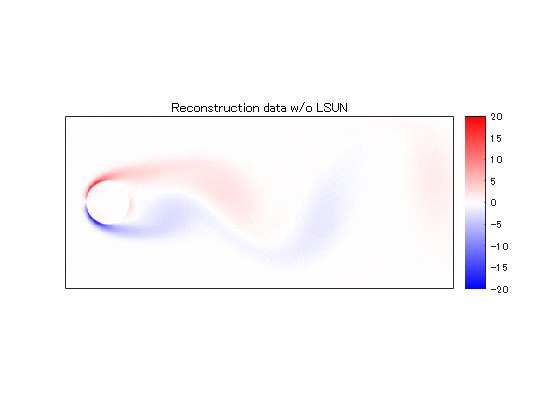

him = [];
for iFrame = 1:nFrames-1
    x = rtn(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
        title('Reconstruction data w/o LSUN')
    end
    drawnow
end

## piDMD w/ (POD mode truncation after) dimensional reduction via LSUN

- Train LSUN 

- Project data onto the LSUN feature space

- Apply piDMD

### Train LSUN

% Decimation factor (Strides)
blksz = 4.*[1 1]; % Block size
stride = blksz; % [My Mx]
% Number of overlapping blocks (Polyphase order plus one)
nof = 2;
ky = 2*nof+1; % # of overlapping blocks (odd number)
kx = 2*nof+1;
ovlpFactor = [ky kx];
% # of coeffs
nCoefs = 2;
% Max epochs
maxEpochs = 4;
% Mini batch size
miniBatchSize = 5;
% Standard deviation of initial angles
stdInitAng = 1e-6;
% No DC-leakage
noDcLeakage = false;
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Block size                           [%d %d]  \n',blksz));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ky,kx));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('Max epochs                           [%d]     \n',maxEpochs));
strbuf = strbuf.append(sprintf('Mini batch size                      [%d]     \n',miniBatchSize));
strbuf = strbuf.append(sprintf('Standard deviation of initial angles [%d]     \n',stdInitAng));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('--------------------------------------------     \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Block size                           [4 4]  
Strides                              [4 4]  
Overlapping blocks                   [5 5]  
nCoef                                [2]     
Max epochs                           [4]     
Mini batch size                      [5]     
Standard deviation of initial angles [1.000000e-06]     
No DC-leakage                        [0]     
--------------------------------------------     



### Pad array

szy = ceil(nrows/blksz(1))*blksz(1);
szx = ceil(ncols/blksz(2))*blksz(2);
% Pad zeros to make the size multiples of nDecs.
vtpad = padarray(vt,[szy szx]-[nrows ncols],0,'post');

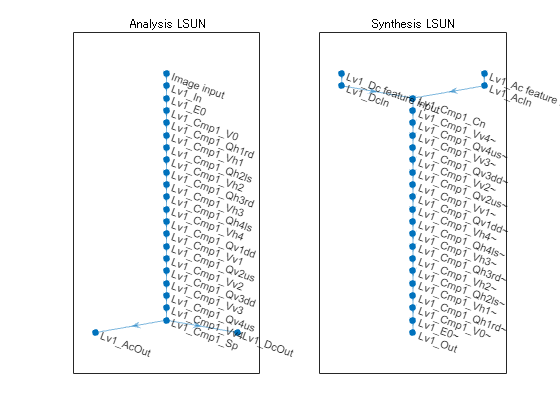

import tansacnet.lsun.*
analysislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

### Construction of synthesis/analysis network

% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        analysisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
    
import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vh3 to Lv1_Cmp1_Vh3~
Copy angles from Lv1_Cmp1_Vh4 to Lv1_Cmp1_Vh4~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~
Copy angles from Lv1_Cmp1_Vv3 to Lv1_Cmp1_Vv3~
Copy angles from Lv1_Cmp1_Vv4 to Lv1_Cmp1_Vv4~


synthesisnet = dlnetwork(synthesislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

x = rand([szy szx],'double');
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 1.7974e-09"



## Parameter optimization and approximation

### Create analysis layerGraph

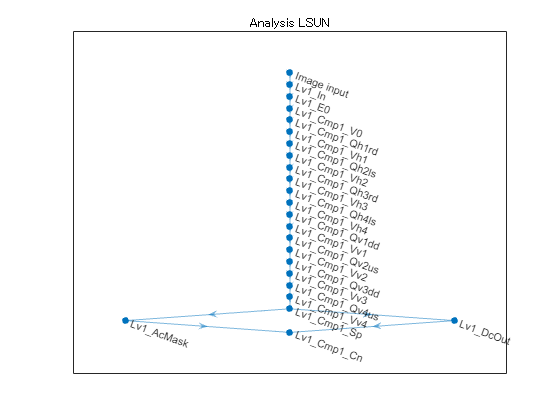

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);

% Coefficient masking
nChsTotal = prod(stride);
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end

% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
%      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']) ...
%      lsunRegressionLayer('Coefficient output')
%     ]);
analysislgraph = analysislgraph.addLayers(...
      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

figure
plot(analysislgraph)
title('Analysis LSUN')

### Training Data Set w/ Noise

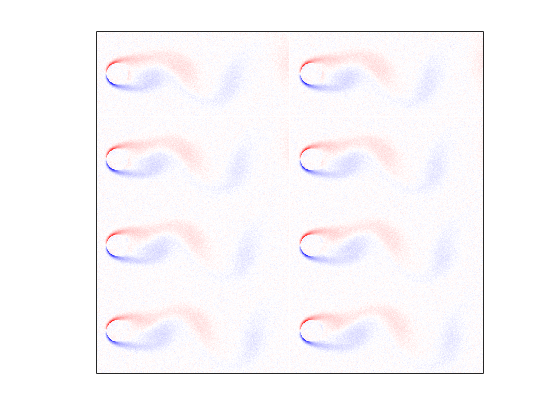

% Image data store
arrds = arrayDatastore(vtpad(:,:,1:end-1),'IterationDimension',3);
figure
dataOut = preview(arrds);
tile = imtile(dataOut);
mycylinderplot_([],tile,clims);

drawnow

## Training phase

numimgs = nFrames-1;
mbq = minibatchqueue(arrds,...
    'MiniBatchSize',miniBatchSize,...
    'OutputAsDlarray',1,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat','SSCB',...
    'OutputCast','double',...
    'OutputEnvironment','gpu');
shuffle(mbq)
dlX = next(mbq);
trainnet = dlnetwork(analysislgraph,dlX);
trainnet.Initialized   

ans = logical
   1


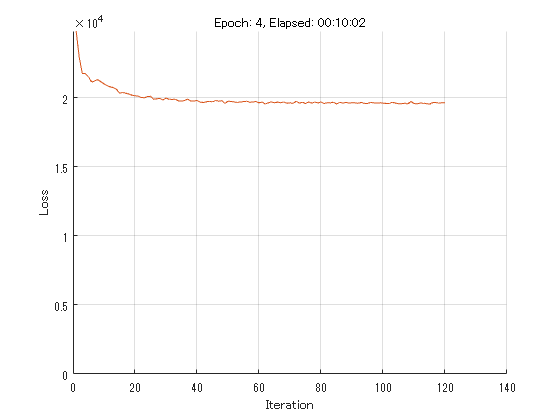

% Configuration
figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

velocity = [];
iteration = 0.01;
momentum = 0.9;
decay = 0.01;
initialLearnRate = 1e-4;

% Loop over epochs.
start = tic;
for epoch = 1:maxEpochs

    % Shuffle data.
    shuffle(mbq)

    while hasdata(mbq)
        % Loop over mini-batches.
        iteration = iteration + 1;
    
        % Read mini-batch of data.
        dlX = next(mbq);

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,loss] = dlfeval(@modelGradients,trainnet,dlX);
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);

        % Update the network parameters using the SGDM optimizer.
        [trainnet,velocity] = sgdmupdate(trainnet,gradients,velocity,learnRate,momentum);

        % Display the training progress.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
end

lsunresfile = "../../../results/lsun4pidmd"+string(datetime('now','TimeZone','local','Format','yyyy-M-dd-HH-mm-ssZ'))

lsunresfile = "../../../results/lsun4pidmd2024-3-15-09-07-40+0900"

save(lsunresfile,"trainnet","szy","szx","nCoefs");

## Inference phase

%lsunresfile = "../../../results/lsun4pidmd2024-3-11-06-07-39+0900";
load(lsunresfile)

### Construction of LSUN-base linear autoencoder 

nLevels = extractnumlevels(trainnet);
stride = extractstride(trainnet);
ovlpFactor = extractovlpfactor(trainnet);
noDcLeakage = extractnodcleakage(trainnet);
szExt = [szy szx];
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ovlpFactor(1),ovlpFactor(2)));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('Extended size                        [%d %d]  \n',szy,szx));
strbuf = strbuf.append(sprintf('--------------------------------------------  \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Strides                              [4 4]  
Overlapping blocks                   [5 5]  
nCoef                                [2]     
No DC-leakage                        [0]     
Extended size                        [200 452]  
--------------------------------------------  



import tansacnet.lsun.*
lsunana4predict = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
lsunsyn4predict = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
trainlgraph = layerGraph(trainnet);
lsunsyn4predict = fcn_cpparamsana2syn(lsunsyn4predict,trainlgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vh3 to Lv1_Cmp1_Vh3~
Copy angles from Lv1_Cmp1_Vh4 to Lv1_Cmp1_Vh4~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~
Copy angles from Lv1_Cmp1_Vv3 to Lv1_Cmp1_Vv3~
Copy angles from Lv1_Cmp1_Vv4 to Lv1_Cmp1_Vv4~



lsunana4predict = fcn_cpparamssyn2ana(lsunana4predict,lsunsyn4predict);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4


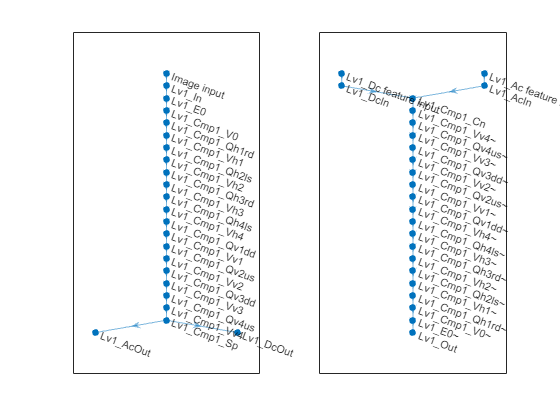

figure
subplot(1,2,1)
plot(lsunana4predict)
subplot(1,2,2)
plot(lsunsyn4predict)

## Linear autoencoder with LSUN

### Assemble analyzer

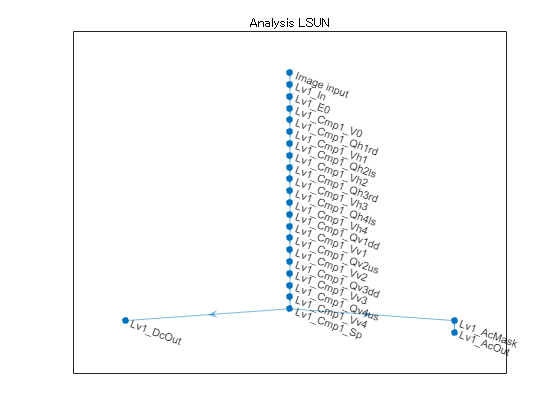

% Coefficient masking
nChsTotal = prod(stride);
isPR = false;
if isPR
    nCoefs = nChsTotal;
end
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];

iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
lsunana4predict = lsunana4predict.disconnectLayers([strLv 'Cmp1_Sp/ac'],[strLv 'AcOut']);
lsunana4predict = lsunana4predict.addLayers(...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
lsunana4predict = lsunana4predict.connectLayers(...
    [strLv 'Cmp1_Sp/ac'],[strLv 'AcMask']);
lsunana4predict = lsunana4predict.connectLayers(...
    [strLv 'AcMask'],[strLv 'AcOut']);
for iLayer = 1:height(lsunana4predict.Layers)
    layer = lsunana4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        lsunana4predict = lsunana4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end

figure
plot(lsunana4predict)
title('Analysis LSUN')

analysislsun4predict = assembleNetwork(lsunana4predict);

### Assemble synthesizer 

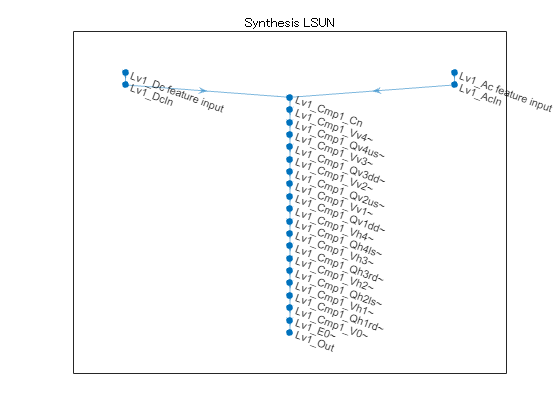

lsunsyn4predict = lsunsyn4predict.replaceLayer('Lv1_Out',...
    regressionLayer('Name','Lv1_Out'));
for iLayer = 1:height(lsunsyn4predict.Layers)
    layer = lsunsyn4predict.Layers(iLayer);
    if contains(layer.Name,'Ac feature input')
        iLv = str2double(layer.Name(3));
        sbSize = szExt.*(stride.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize (sum(nChsTotal)-1)],'Name',layer.Name,'Normalization','none');
        lsunsyn4predict = lsunsyn4predict.replaceLayer(...
            layer.Name,newlayer);
    elseif contains(layer.Name,sprintf('Lv%0d_Dc feature input',nLevels))
        iLv = str2double(layer.Name(3));
        sbSize = szExt.*(stride.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize 1],'Name',layer.Name,'Normalization','none');
        lsunsyn4predict = lsunsyn4predict.replaceLayer(...
            layer.Name,newlayer);
    end
end

figure
plot(lsunsyn4predict)
title('Synthesis LSUN')

synthesislsun4predict = assembleNetwork(lsunsyn4predict);

### Check reconstruction

analysislsun4predict.Layers

ans =   次の層をもつ 24×1 の Layer 配列:

     1   'Image input'      イメージの入力                                      200×452×1 イメージ
     2   'Lv1_In'           tansacnet.lsun.lsunIdentityLayer                 Identity
     3   'Lv1_E0'           tansacnet.lsun.lsunBlockDct2dLayer               Block DCT of size 4x4
     4   'Lv1_Cmp1_V0'      tansacnet.lsun.lsunInitialRotation2dLayer        LSUN initial rotation (ps,pa) = (8,8), (mv,mh) = (4,4)
     5   'Lv1_Cmp1_Qh1rd'   tansacnet.lsun.lsunAtomExtension2dLayer          Right shift the difference-channel Coefs. (ps,pa) = (8,8)
     6   'Lv1_Cmp1_Vh1'     tansacnet.lsun.lsunIntermediateRotation2dLayer   Analysis LSUN intermediate rotation (ps,pa) = (8,8)
     7   'Lv1_Cmp1_Qh2ls'   tansacnet.lsun.lsunAtomExtension2dLayer          Left shift the sum-channel Coefs. (ps,pa) = (8,8)
     8   'Lv1_Cmp1_Vh2'     tansacnet.lsun.lsunIntermediateRotation2dLayer   Analysis LSUN int

synthesislsun4predict.Layers

ans =   次の層をもつ 24×1 の Layer 配列:

     1   'Lv1_DcIn'               tansacnet.lsun.lsunComponentSeparation2dLayer    tansacnet.lsun.lsunComponentSeparation2dLayer
     2   'Lv1_AcIn'               tansacnet.lsun.lsunComponentSeparation2dLayer    tansacnet.lsun.lsunComponentSeparation2dLayer
     3   'Lv1_Cmp1_Cn'            tansacnet.lsun.lsunChannelConcatenation2dLayer   Channel concatenation
     4   'Lv1_Cmp1_Vv4~'          tansacnet.lsun.lsunIntermediateRotation2dLayer   Synthesis LSUN intermediate rotation (ps,pa) = (8,8)
     5   'Lv1_Cmp1_Qv4us~'        tansacnet.lsun.lsunAtomExtension2dLayer          Down shift the sum-channel Coefs. (ps,pa) = (8,8)
     6   'Lv1_Cmp1_Vv3~'          tansacnet.lsun.lsunIntermediateRotation2dLayer   Synthesis LSUN intermediate rotation (ps,pa) = (8,8)
     7   'Lv1_Cmp1_Qv3dd~'        tansacnet.lsun.lsunAtomExtension2dLayer          Up shift the difference-channel Coefs. 

% sigmaw = 0.49996
load("../../../results/noisyflow_"+replace(num2str(sigmaw),'.','_'),"ut","vt")
nrows = size(ut,1);
ncols = size(ut,2);

### Pad array

szy = ceil(nrows/blksz(1))*blksz(1);
szx = ceil(ncols/blksz(2))*blksz(2);
% Pad zeros to make the size multiples of nDecs.
vtpad = padarray(vt,[szy szx]-[nrows ncols],0,'post');

if isPR 
    x = gpuArray(randn(szy,szx,'double'));
else
    x = gpuArray(vtpad(:,:,1));
end
[s{1:nLevels+1}] = analysislsun4predict.predict(x);
y = synthesislsun4predict.predict(s{nLevels+1:-1:1}); % FIXME: Order of AC & DC should be flipped
if isPR
    display("MSE: " + num2str(mse(x,y)))
else
    xorg = ut(:,:,1);
    yapx = y(1:nrows,1:ncols);
    display("MSE: " + num2str(mse(xorg,yapx)))
end

    "MSE: 0.033795"



## Define the LSUN analyzer and synthesizer

nLayers = height(analysislsun4predict.Layers);
for iLayer = 1:nLayers
    layer = analysislsun4predict.Layers(iLayer);
    if strcmp(layer.Name,"Lv1_AcMask")
        acMask = logical(squeeze(layer.Mask));
    end
end
analyzer_ = @(x) fcn_lsunanalyzer_(x,analysislsun4predict,acMask); % Analyze array x, and vectorize the result
synthesizer_ = @(x) fcn_lsunsynthesizer_(x,synthesislsun4predict,acMask); % Reshape x and synthesize the result 

## piDMD w/ POD mode truncation via LSUN

### Project X and Y onto the LSUN feature space

vtpad = gpuArray(vtpad);
Xlsun = analyzer_(vtpad(:,:,1:nFrames-1)); 
Ylsun = analyzer_(vtpad(:,:,2:nFrames));

### Apply piDMD w/ POD mode truncation

[piA2, piVals2, piVecs2, projA2] = piDMD(Xlsun,Ylsun,'orthogonal',nModes4PODtrunc); 

## Time evolution via piDMD in transform domain

Rlsun = zeros(size(Xlsun)+[0 1],'like',Xlsun);
b = piVecs2'*Xlsun(:,1);
precoefs = b;
for iFrame = 1:nFrames-1
    coefs = diag(piVals2)*precoefs;
    Rlsun(:,iFrame+1) = real(piVecs2*coefs); % Take real only for numerical error correction
    precoefs = coefs;    
end

### Project back to original space

rtpad = synthesizer_(Rlsun);
rtlsun = rtpad(1:nrows,1:ncols,:);

## Reconstruction Data Visualization

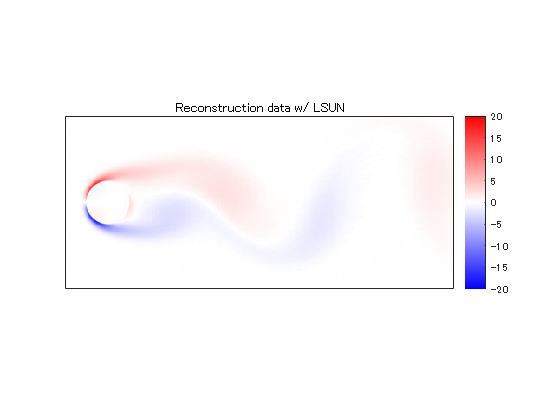

him = [];
for iFrame = 1:nFrames-1
    x = rtlsun(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
        title('Reconstruction data w/ LSUN')
    end
    drawnow
end

## Plot some results

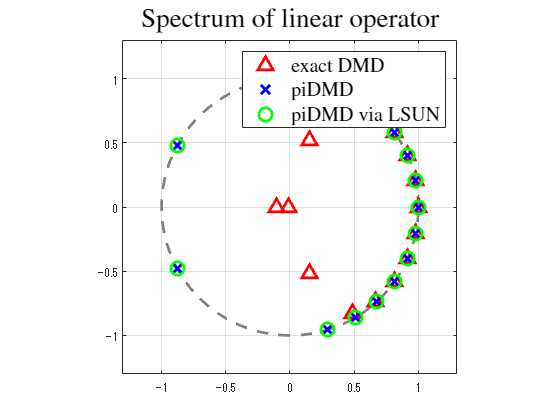

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; LW = 'LineWidth';
%
figure
clf
plot(exp(1i*linspace(0,2*pi)),'--','Color',[1 1 1]*.5,LW,2)
hold on
p2 = plot((exVals)+1i*eps,'r^',LW,2,MS,10);
p3 = plot((piVals1)+1i*eps,'bx',LW,2,MS,10);
p4 = plot((piVals1)+1i*eps,'go',LW,2,MS,10);

grid on; axis equal; hold off
axis(1.3*[-1,1,-1,1])

legend([p2,p3,p4],{'exact DMD','piDMD', 'piDMD via LSUN'},FS,15,IN,LT)
title('Spectrum of linear operator',FS,20,IN,LT)

## Local functions

### LSUN Analyzer

function Xlsun = fcn_lsunanalyzer_(x,analyzer,acMask)
nFrames = size(x,3);
nLevels = 1;
szy = size(x,1);
szx = size(x,2);
stride = extractstride(analyzer);
Xlsun = zeros(szy*szx*(1+sum(acMask))/prod(stride),nFrames,'like',x);
for iFrame = 1:nFrames
    [s{1:nLevels+1}] = analyzer.predict(x(:,:,iFrame));
    dc = s{1};
    ac = s{end};
    ac = ac(:,:,acMask); % Shrink
    Xlsun(:,iFrame) = reshape(cat(3,dc,ac),[],1);
end
end

### LSUN Synthesizer

function x = fcn_lsunsynthesizer_(Xlsun,synthesizer,acMask)
nLevels = 1;
nLayers = height(synthesizer.Layers);
for iLayer = 1:nLayers
    layer = synthesizer.Layers(iLayer);
    if strcmp(layer.Name,"Lv1_Ac feature input")
        szac = layer.InputSize;
    end
end
nFrames = size(Xlsun,2);
stride = extractstride(synthesizer);
x = zeros(szac(1)*stride(1),szac(2)*stride(2),nFrames);
s = cell(nLevels+1,1);
ac = zeros(szac,'like',Xlsun);
for iFrame = 1:nFrames
    xlsun = reshape(Xlsun(:,iFrame),szac(1),szac(2),[]);
    s{1} = xlsun(:,:,1);
    % Extension
    ac(:,:,acMask) = xlsun(:,:,2:end);
    s{nLevels+1} = ac;
    x(:,:,iFrame) = synthesizer.predict(s{nLevels+1:-1:1});
end
end

### Definition of Drawing Function

function him = mycylinderplot_(him,x,clims)
if isempty(him)
    figure
    him = imagesc(x,clims);
    axis equal
    axis tight
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    cmap = zeros(256,3);
    cmap(128:255,1) = 1;
    cmap(1:127,3) = 1;
    hsv = rgb2hsv(permute(cmap,[1 3 2]));
    hsv(:,2) = [254:-2:0 1:2:255].'/255;
    cmap = ipermute(hsv2rgb(hsv),[1 3 2]); 
    colormap(cmap)
else
    him.CData = x;
end
end

### Gradients w.r.t. LSUN design parameters

function [gradients, loss] = modelGradients(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

### MiniBatch function

function X = preprocessMiniBatch(XCell)
    % Extract image data from the cell array and concatenate over fourth
    % dimension to add a third singleton dimension, as the channel
    % dimension.
    X = cat(4,XCell{:});
end

### Information extractors

function nLevels = extractnumlevels(lsun)
import tansacnet.lsun.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

function stride = extractstride(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        stride = layer.Stride;
    end
end
end

function ovlpFactor = extractovlpfactor(lsun)
import tansacnet.lsun.*

% Extraction of information
expanalyzerv = '^Lv\d+_Cmp\d+_Vv(\d)+$';
expanalyzerh = '^Lv\d+_Cmp\d+_Vh(\d)+$';
nLayers = height(lsun.Layers);
ovlph = 1;
ovlpv = 1;
for iLayer = 1:nLayers
    alayer = lsun.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzerv,'once'))
        ovlpv = ovlpv + 1;
    elseif ~isempty(regexp(alayerName,expanalyzerh,'once'))
        ovlph = ovlph + 1;
    end
end

ovlpFactor = [ovlpv ovlph];

end

function noDcLeakage = extractnodcleakage(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        noDcLeakage = layer.NoDcLeakage;
    end
end

end